clear all 
close all
Path = 'C:\SortingFolder\HIP\CSI_Boottstrap.xlsx';

% Import table
HIP_Multi  = readtable(Path);
HIParray = table2array(HIP_Multi(:,["CSI","Rango_1","Rango_2"]));
% HIParray(any(isnan(HIParray), 2), :) = [];

load 'D:\Jazmin\Multichannel Data Tanks\Cortex\SignificanceWindowTable_MUA.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
load 'D:\Jazmin\Multichannel Data Tanks\Cortex\SignificanceWindowTable.mat';

SignificanceWindowTable = [SignificanceWindowTableMUA;SignificanceWindowTable];

% Significance 
n= 1;
for i = 1: size(SignificanceWindowTable,1)
    if (SignificanceWindowTable.SignificanceDEV1(i,1) + SignificanceWindowTable.SignificanceDEV2(i,1)) > 1
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end
end

n=0;
for i = 1:size(SIscatterIndx,1)
    n=n+1;
    HIParrayAuditory(n,[1,2,3]) = HIParray(SIscatterIndx(i),:);
end

n=0;
m=0;
for i = 1:size(HIParrayAuditory,1)
    if HIParrayAuditory(i,2)<0 && HIParrayAuditory(i,3)>0
        n = n + 1;
        NonSignificant(n,1) = i;
    else
        m = m + 1;
        Significant(m,1) = i;
    end
end

for j = 1: size(NonSignificant,1)
    CSI_NonSignificant(j,1) = HIParrayAuditory(NonSignificant(j,1),1);
end

for k = 1: size(Significant,1)
    CSI_Significant(k,1) = HIParrayAuditory(Significant(k,1),1);
end

n=0;
for i = 1:size(SIscatterIndx,1)
    n=n+1;
    SignificanceWindowTableAuditory(n,:) = SignificanceWindowTable(SIscatterIndx(i),:);
end

for k = 1: size(Significant,1)
    SignificanceWindowTableAuditorySig(k,:) = SignificanceWindowTableAuditory(Significant(k,1),:);
end

DEV_R = [SignificanceWindowTableAuditorySig.DEV1;SignificanceWindowTableAuditorySig.DEV2];
STD_R = [SignificanceWindowTableAuditorySig.STD1;SignificanceWindowTableAuditorySig.STD2];
CTR_R = [SignificanceWindowTableAuditorySig.CTRCA1;SignificanceWindowTableAuditorySig.CTRCD2];

DEV_P = [SignificanceWindowTableAuditorySig.DEV1P;SignificanceWindowTableAuditorySig.DEV2P];
STD_P = [SignificanceWindowTableAuditorySig.STD1P;SignificanceWindowTableAuditorySig.STD2P];
CTR_P = [SignificanceWindowTableAuditorySig.CTRCA1;SignificanceWindowTableAuditorySig.CTRCA2];

y_R = [DEV_R, CTR_R, STD_R];
y_P = [DEV_P, CTR_P, STD_P];


y_mR = mean(y_R,'omitnan');

y_mP = mean(y_P,'omitnan');

y = [y_mR; y_mP];

b = bar(y, 'grouped');
ylim([0 1]);

hold on
xline(0,'LineWidth',2);
ylabel('Normalized spike count')

RNDEV_std = std(y_R(:,1),'omitnan');
err_RNDEV = RNDEV_std / sqrt(size(y_R(:,1),1))

err_RNDEV = 0.0263


RNCTR_std = std(y_R(:,2),'omitnan');
err_RNCTR = RNCTR_std / sqrt(size(y_R(:,2),1))

err_RNCTR = 0.0093


RNSTD_std = std(y_R(:,3),'omitnan');
err_RNSTD = RNSTD_std / sqrt(size(y_R(:,3),1))

err_RNSTD = 0.0066


PNDEV_std = std(y_P(:,1),'omitnan');
err_PNDEV = PNDEV_std / sqrt(size(y_P(:,1),1))

err_PNDEV = 0.0212


PNCTR_std = std(y_P(:,2),'omitnan');
err_PNCTR = PNCTR_std / sqrt(size(y_P(:,2),1))

err_PNCTR = 0.0080


PNSTD_std = std(y_P(:,3),'omitnan');
err_PNSTD = PNSTD_std / sqrt(size(y_P(:,3),1))

err_PNSTD = 0.0074


y_mRerr = [err_RNDEV err_RNCTR err_RNSTD]

y_mRerr =     0.0263    0.0093    0.0066


y_mPerr = [err_PNDEV  err_PNCTR err_PNSTD]

y_mPerr =     0.0212    0.0080    0.0074



y_err = [y_mRerr; y_mPerr]

y_err =     0.0263    0.0093    0.0066
    0.0212    0.0080    0.0074


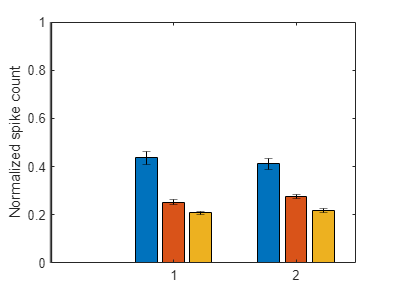


% er = errorbar(y, y_err);
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';

% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(y);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:nbars
    x(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',y,y_err,'k','linestyle','none');

hold off

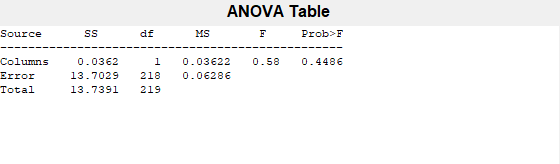

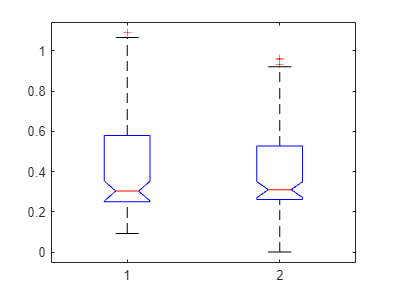

p_dev = 0.4486

 p_dev = anova1([DEV_R DEV_P])

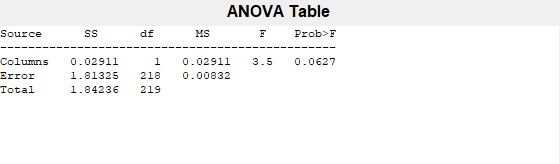

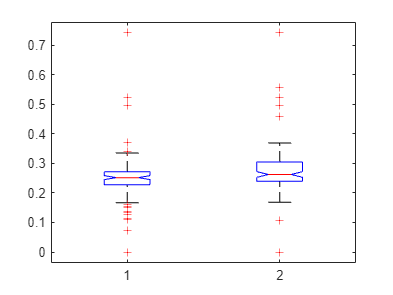

p_ctr = 0.0627

% 
 p_ctr = anova1([CTR_R CTR_P])

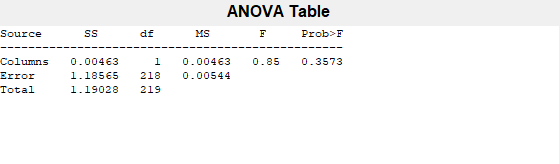

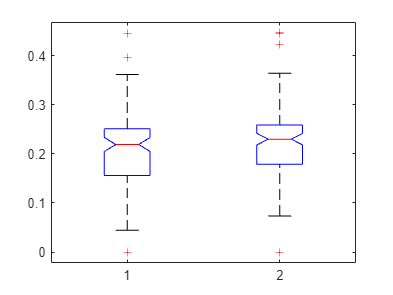

p_std = 0.3573

% 
 p_std = anova1([STD_R STD_P])

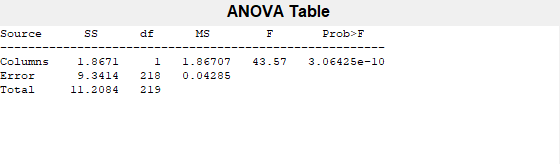

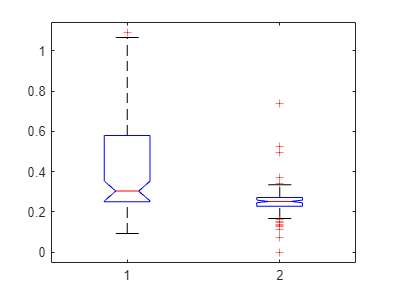

p_dev_ctr = 3.0643e-10


p_dev_ctr = anova1([DEV_R, CTR_R])

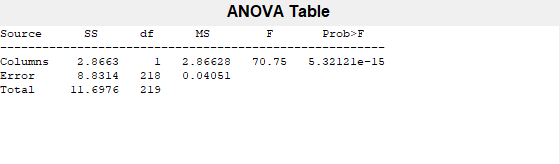

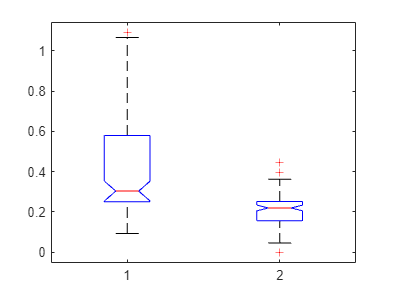

p_dev_std = 5.3212e-15

p_dev_std = anova1([DEV_R, STD_R])

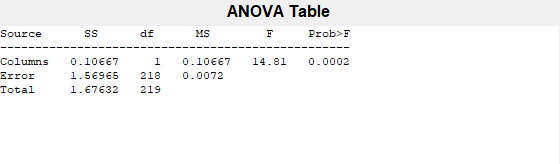

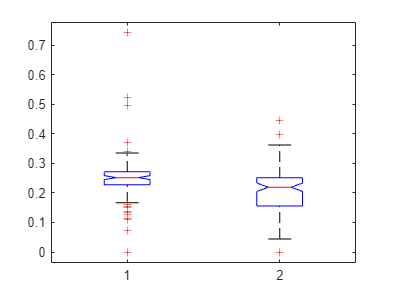

p_ctr_std = 1.5586e-04

p_ctr_std = anova1([CTR_R, STD_R])

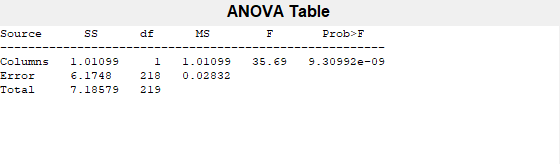

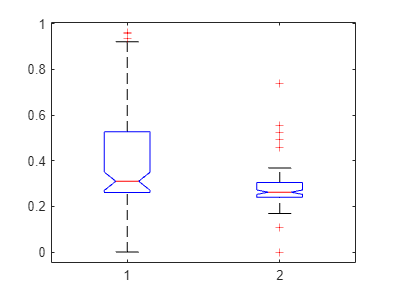

p_dev_ctrP = 9.3099e-09


p_dev_ctrP = anova1([DEV_P, CTR_P])

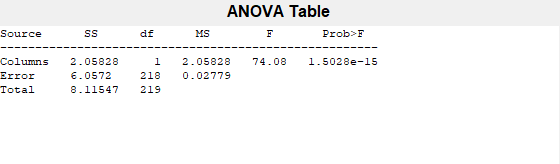

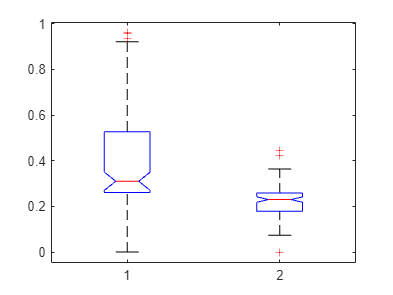

p_dev_stdP = 1.5028e-15

p_dev_stdP = anova1([DEV_P, STD_P])

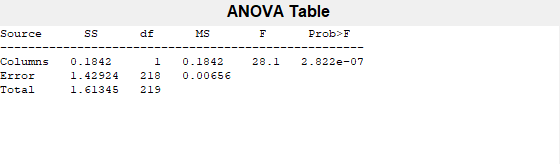

p_ctr_stdP = 2.8220e-07

p_ctr_stdP = anova1([CTR_P, STD_P])

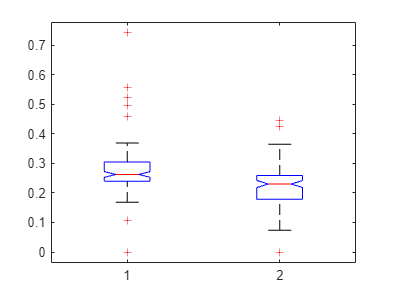

% 
% p_dev = friedman(DEV_R,6)
% 
% p_ctr = friedman(CTR_R,6)
% 
% p_std = friedman(STD_R,6)
% 
% [p_DEV_w,h_DEV_w] = ranksum(DEV_R, DEV_P)
% [p_STD_w,h_STD_w] = ranksum(STD_R, STD_P)
% 
% [p_DEV_w,h_DEV_w] = ranksum(DEV_R, CTR_R)
% [p_DEV_w,h_DEV_w] = ranksum(DEV_R, STD_R)
% [p_CTR_w,h_CTR_w] = ranksum(CTR_R, STD_R)
% 
% [p_DEV_w,h_DEV_w] = ranksum(DEV_P, CTR_P)
% [p_DEV_w,h_DEV_w] = ranksum(DEV_P, STD_P)
% [p_CTR_w,h_CTR_w] = ranksum(CTR_P, STD_P)



cd 'C:\SortingFolder\HIP\BarGraphs';
saveas(gcf,'R_P_err.pdf');
saveas(gcf,'R_P_err.tif');

saveas(gcf,'R_P_err.fig');
